# DEN5302_03: calculate Mean power frequency

y = sensor2;
Fs = 2000;                    % Sampling frequency
T = 1/Fs;                     % Sample time
L = length(y);                % Length of signal
t = (0:L-1)*T;                % Time vector

## Fast Fourier transform(FFT) and Power spectrum

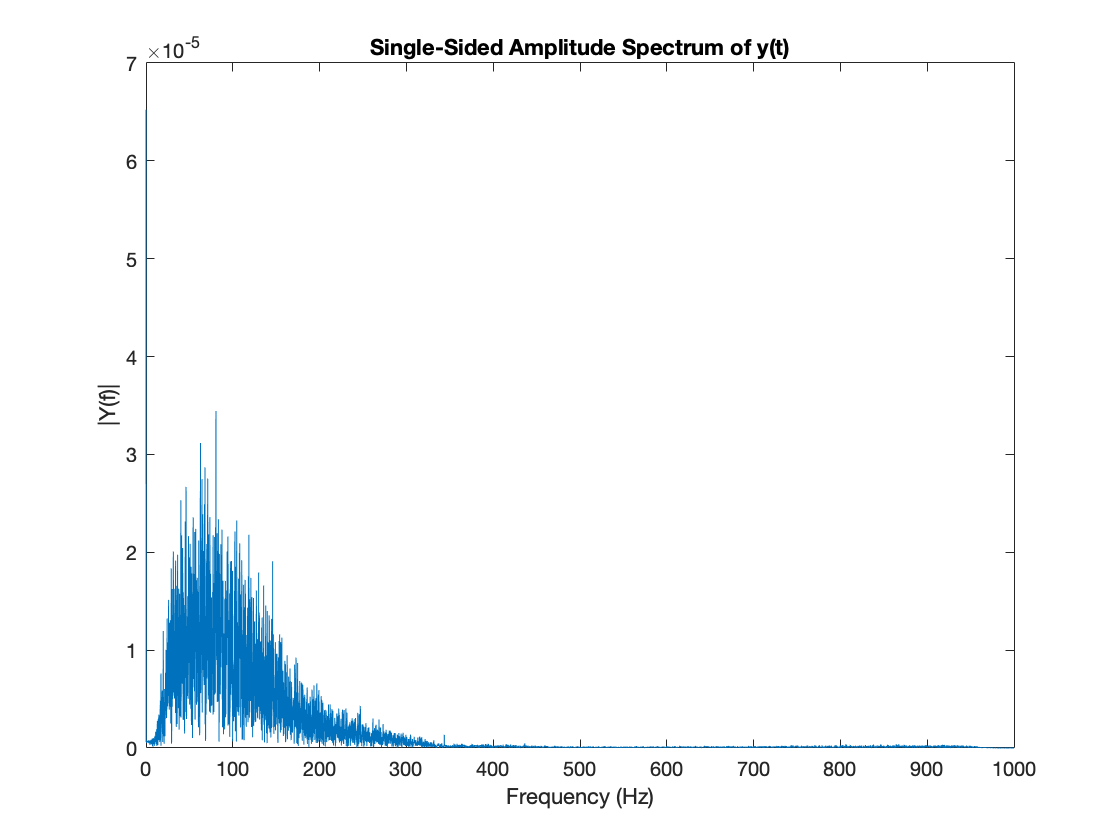

NFFT = 2^nextpow2(L);         % Next power of 2 from length of y
Y = fft(y,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2);

% Plot single-sided amplitude spectrum.
figure
plot(f,2*abs(Y(1:NFFT/2))) 
title('Single-Sided Amplitude Spectrum of y(t)')
xlabel('Frequency (Hz)')
ylabel('|Y(f)|');

## Get Mean Power frequency

s = 2*abs(Y(1:NFFT/2));
MF =  (f*s)/sum(s);
fprintf('MPF =%5.2f\n',MF)

MPF =128.22
